## 1. Initialize values

For calculations of internal shear and bending moments of a loading case of interest (train loading or point loading), they are completed in a later function that plots all values

L = 1250;                   % Length of the bridge being considered
n = 1251;                   % Variable used to initialize arrays for the bridge
x = linspace(0, L, n);      % Define x coordinates for the position on the bridge
P = 200;                    % Point load magnitude (N)

% Initialization for the train load case

SFD_TL = zeros(1, n);       % Initialize SFD for train load 
BMD_TL = zeros(1, n);       % Initialize BMD for train load
config = 2105;              % Number of train load  configurations to test
train = 2;                  % Set to 1 to test for train loading,
                            % anything else for point loading

## 2. Define cross-section and calculate cross-sectional properties

Defined in 1-D arrays to specify changes in the design's cross section

% Define cross section design

xc = [0 20 330 788 980];            % Location, x, of cross-section change 
bft = [100 100 100 100 100];        % Top flange width 
tft = [1.27 1.27 2.54 1.27 2.54];   % Top flange thickness
btgt = [10 10 10 10 10];            % Top glue tab width
ttgt = [1.27 1.27 1.27 1.27 1.27];  % Top glue tab thickness
hw = [(145-1.5) (145-1.5) (145-1.5-1.27) (145-1.27-1.5) (145-1.27-1.5)...
  (145-1.27-1.5) (145-3*1.27-1.5)]; % Web height 
tw = [1.27 1.27 1.27 1.27 1.27];    % Web thickness (thickness of one web)
bfb = [65 0 0 65 65];               % Bottom flange width 
tfb = [1.27 0 0 2.54 3.81];         % Bottom flange thickness 
bbgt = [10 0 0 10 10];              % Bottom glue tab width
tbgt = [1.27 1.27 1.27 1.27 1.27];  % Bottom glue tab thickness
ws = [(65-2.54) (65-2.54) (65-2.54)...
      (65-2.54) (65-2.54)];         % Distance between the outer edge of the webs
a = [15 260 260 30 120 120 120 120 30 80 80]; % Distance between diaphragms

% Design 0 Properties

% xc = [0];                   % Location, x, of cross-section change 
% bft = [100];                % Top flange width 
% tft = [1.27];               % Top flange thickness
% btgt = [10];                % Top blue tab width
% ttgt = [1.27];              % Top blue tab thickness
% hw = [(75 - 1.27*2)];       % Web Height 
% tw = [1.27];                % Web thickness (assuming 2 separate webs) 
% bfb = [80];                 % Bottom flange width 
% tfb = [1.27];               % Bottom flange thickness 
% bbgt = [0];                 % Bottom glue tab width
% tbgt = [0];                 % Bottom glue tab thickness
% ws = [80];                  % Distance between the outer edge of the webs
% a = [30 520 30 480 30 160]; % Distance between diaphragms 

% Return cross-sectional properties of interest 

[y_bar0, I0, Q0, h0, tw0, btgt0, bbgt0, Q_gt0, Q_gb0, a0, ws0, hw0, tft0,...
 tfb0, bft0, bfb0] = ...
 SectionProperties(xc, bft, tft, btgt, ttgt, hw, tw, bfb, tfb, bbgt, tbgt, n, a, ws);

## 3. Define material properties 

Given matboard and glue material properties

SigT = 30; 
SigC = 6; 
E    = 4000; 
TauU = 4; 
TauG = 2; 
mu   = 0.2; 

## 4. Loading case analysis of shear and bending moment failures

Constructed in a for loop to allow for plotting of shear and bending moment failure diagrams based on loading case, as well as testing over a range of possible loading scenarios for train loading.

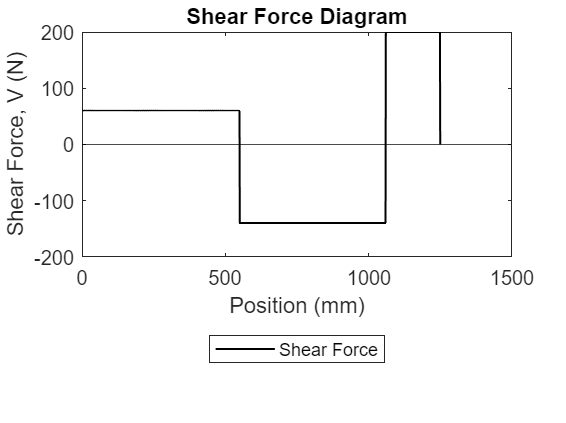

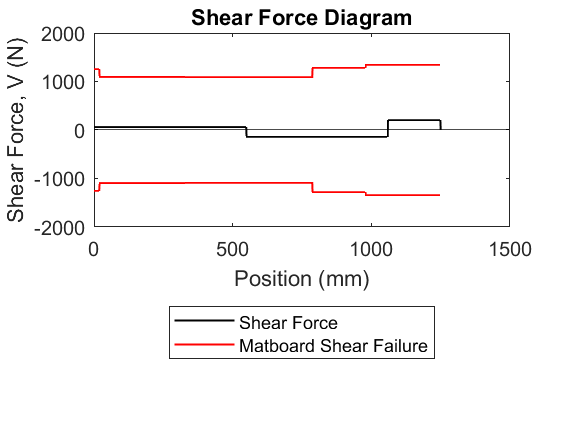

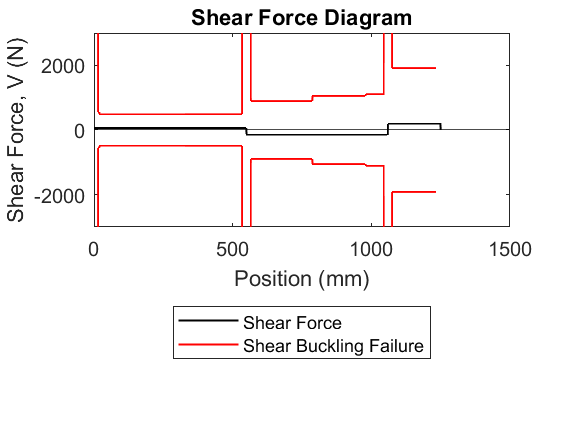

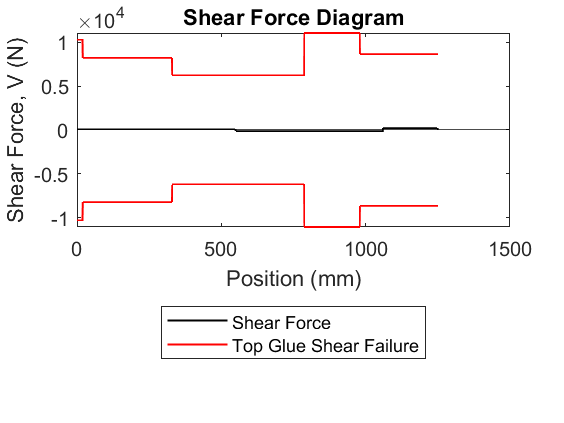

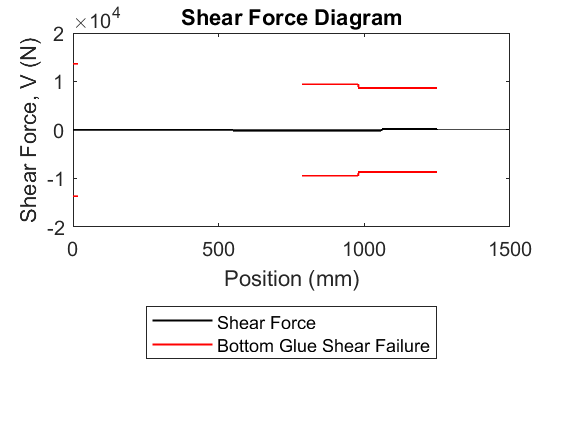

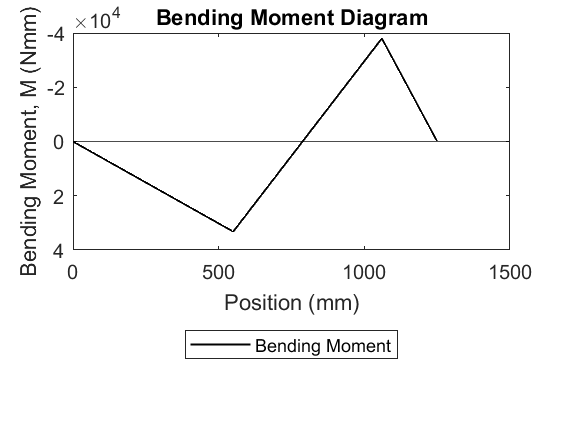

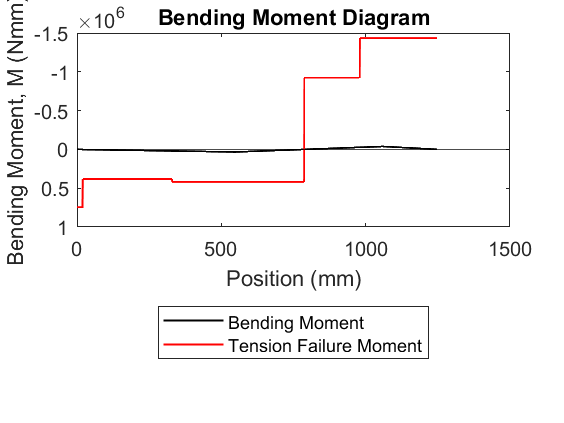

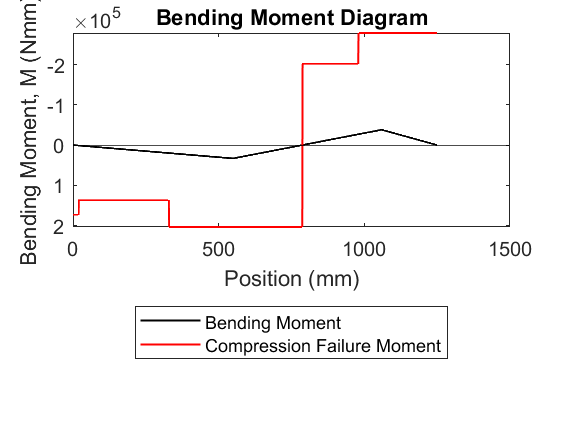

FOS_V1f = 6.7329

FOS_V2f = 6.3956

FOS_V3f = 43.1505

FOS_V4f = 43.3295

FOS_M1f = 6.1314

FOS_M2f = 12.5975

FOS_M3f = 7.6897

FOS_M4f = 7.1018

FOS_M5f = 15.0151

FOS_M6f = 7.3651e+03

FOS_M7f = 31.1397

FOS_M8f = 7.9069

FOS_V = 6.3956

FOS_M = 6.1314

P_fail = 1.2263e+03

if train == 1  % Train loading case
               % Loop through all different train configurations on the bridge
    for civ = 1:config  
        % "civ" is just a counter variable,
        % it needed a unique name to differentiate it from others

        % Skip past scenarios where the wheels are directly under support B
        if civ == 1060 || civ == 1236 || civ == 1400 || civ == 1576 || civ == 1740 || ...
        civ == 1916
            civ = civ + 1;
        end
        % Choose a different array of wheel positions depending on how many 
        % are on the bridge 
        if civ < 177
            xP = [0+civ];
        elseif civ < 341
            xP = [0+civ,-176+civ];
        elseif civ < 517
            xP = [0+civ,-176+civ,-340+civ];
        elseif civ < 681
            xP = [0+civ,-176+civ,-340+civ,-516+civ];
        elseif civ < 857
            xP = [0+civ,-176+civ,-340+civ,-516+civ,-680+civ];
        elseif civ < 1251
            xP = [0+civ,-176+civ,-340+civ,-516+civ,-680+civ,-856+civ];
        elseif civ < 1427
            xP = [-176+civ,-340+civ,-516+civ,-680+civ,-856+civ];
        elseif civ < 1591
            xP = [-340+civ,-516+civ,-680+civ,-856+civ];
        elseif civ < 1767
            xP = [-516+civ,-680+civ,-856+civ];
        elseif civ < 1931
            xP = [-680+civ,-856+civ];
        else
            xP = [-856+civ];
        end
        % Continuously compute the SFD and BMD of the train load
        [SFD_TL, BMD_TL] = TrainL(xP, 66.7, SFD_TL, BMD_TL, n, civ);   
    end
    
    % Extract respective max and min values of SFD and BMD for train values, as
    % opposed to all calculated values 
    SFD_TL_max = max(SFD_TL); 
    SFD_TL_min = min(SFD_TL);
    BMD_TL_max = max(BMD_TL);
    BMD_TL_min = min(BMD_TL);
    
    % Calculate bending moment failures due to tension and compression for
    % both max positive and negative SFD and BMD
    M_MatT_max = MfailMatT(h0, y_bar0, I0, SigT, BMD_TL_max, n);
    M_MatT_min = MfailMatT(h0, y_bar0, I0, SigT, BMD_TL_min, n);
    M_MatC_max = MfailMatC(h0, y_bar0, I0, SigC, BMD_TL_max, n); 
    M_MatC_min = MfailMatC(h0, y_bar0, I0, SigC, BMD_TL_min, n); 
    
    % Calculate matboard shear and glue tab shear failures 
    % Need to consider top and bottom glue tabs for glue tab shear failures
    V_fail_mat = Vfail_matboard(I0, tw0, Q0, TauU);
    V_fail_glue_top = Vfail_glue(I0, btgt0, Q_gt0, TauG);
    V_fail_glue_bot = Vfail_glue(I0, bbgt0, Q_gb0, TauG);
    
    % Calculate shear and flexural buckling failures
    V_buck_fail = Vfailbuck(tw0, a0, hw0, E, mu, I0, Q0);
    % These are 2 arrays since there are 2 seperate BMDs, one for the max
    % positive and one for the max negative
    [M_Buck_side_top_max, M_Buck_mid_top_max, M_Buck_web_top_max,...
     M_Buck_side_bot_max, M_Buck_mid_bot_max, M_Buck_web_bot_max]...
     = MfailBuck(tft0, tfb0, bft0, bfb0, tw0, h0, ws0, y_bar0, E, mu,...
     BMD_TL_max, n, I0);
    [M_Buck_side_top_min, M_Buck_mid_top_min, M_Buck_web_top_min,...
     M_Buck_side_bot_min, M_Buck_mid_bot_min, M_Buck_web_bot_min]...
     = MfailBuck(tft0, tfb0, bft0, bfb0, tw0, h0, ws0, y_bar0, E, mu,...
     BMD_TL_min, n, I0);

    % Combine all tens. and comp. failures, flexural buckling failures,
    % BMDs, and SFDS into matrices to be used later
    M_MatC = [M_MatC_max;M_MatC_min];
    M_MatT = [M_MatT_max;M_MatT_min];
    M_flexbuck = [M_Buck_side_top_max;M_Buck_mid_top_max;M_Buck_web_top_max;...
    M_Buck_side_bot_min;M_Buck_mid_bot_min;M_Buck_web_bot_min];
    M_flexbuck(M_flexbuck == 0) = NaN; % Remove values of 0 so other functions can work
    BMD_TL = [BMD_TL_max;BMD_TL_min];
    SFD_TL_plot = [SFD_TL_max;SFD_TL_min];
    SFD_TL = max(abs([SFD_TL_max;SFD_TL_min]));

    % Run the function that plots all the modes of failure against the SFD
    % and BMD
    VisualizePL(x, SFD_TL_plot, BMD_TL, V_fail_mat, V_buck_fail, V_fail_glue_top, ...
    V_fail_glue_bot, M_MatT, M_MatC, M_flexbuck, train);

    % Run the FOS function
    [FOS_V, FOS_M] = Fact_of_Safe(V_fail_mat, V_buck_fail, V_fail_glue_top, ...
     V_fail_glue_bot, M_MatC, M_MatT, M_flexbuck, SFD_TL, BMD_TL, train)

else % Point loading case

    % Extract the SFD and BMD values
    [SFD_PL, BMD_PL] = ApplyPL(P);

    % Calculate the tension and compression failure moments
    M_MatT = MfailMatT(h0, y_bar0, I0, SigT, BMD_PL, n);
    M_MatC = MfailMatC(h0, y_bar0, I0, SigC, BMD_PL, n); 
    
    % Calculate the matboard and glue shear failure
    V_fail_mat = Vfail_matboard(I0, tw0, Q0, TauU);
    V_fail_glue_top = Vfail_glue(I0, btgt0, Q_gt0, TauG);
    V_fail_glue_bot = Vfail_glue(I0, bbgt0, Q_gb0, TauG);
    
    % Calculate the shear buckling and flexural buckling failures
    V_buck_fail = Vfailbuck(tw0, a0, hw0, E, mu, I0, Q0);
    [M_Buck_side_top, M_Buck_mid_top, M_Buck_web_top, M_Buck_side_bot, ...
     M_Buck_mid_bot, M_Buck_web_bot] = ...
     MfailBuck(tft0, tfb0, bft0, bfb0, tw0, h0, ws0, y_bar0, E, mu, BMD_PL, n, I0);
    
    % Turn the flexural buckling into a matrix containing all the different
    % cases
    M_flexbuck = [M_Buck_side_top;M_Buck_mid_top;M_Buck_web_top;M_Buck_side_bot;...
    M_Buck_mid_bot;M_Buck_web_bot];
    M_flexbuck(M_flexbuck == 0) = NaN; % Remove all values of 0 so other functions work
    
    % Run the function that plots all the failure modes against the BMD and
    % SFD
    VisualizePL(x, SFD_PL, BMD_PL, V_fail_mat, V_buck_fail, V_fail_glue_top, ...
    V_fail_glue_bot, M_MatT, M_MatC, M_flexbuck, train);

    % Run FOS and failure load functions
    [FOS_V, FOS_M] = Fact_of_Safe(V_fail_mat, V_buck_fail, V_fail_glue_top, ...
     V_fail_glue_bot, M_MatC, M_MatT, M_flexbuck, SFD_PL, BMD_PL, train)
    P_fail = FailLoad(P, SFD_PL, BMD_PL, V_fail_mat, V_buck_fail, V_fail_glue_top, ...
    V_fail_glue_bot, M_MatC, M_MatT, M_flexbuck)
end

## 5. Calculate mid-span deflection under two applied points loads of P = 200 N

% Run the code that calculates the midspan deflection for point loads of
% 200N, if point loads are calculated

if train ~= 1
    Deflection_midspan = Deflections(BMD_PL, I0, E, n)
end

Deflection_midspan = 0.4237

## 6. Function Calls and Sample Outputs

% [y_bar0, I0, Q0, h0, tw0, btgt0, bbgt0, Q_gt0, Q_gb0, a0, ws0, hw0, ...
%  tft0, tfb0, bft0, bfb0] = SectionProperties(xc, bft, tft, btgt, ttgt, ...
%  hw, tw, bfb, tfb, bbgt, tbgt, n, a, ws)
% 
% [SFD_TL, BMD_TL] = TrainL([900,724,560,384,220,44], 66.7, SFD_TL,BMD_TL,n, 1)
% [SFD_PL, BMD_PL] = ApplyPL(P)
% 
% V_fail_mat = Vfail_matboard(I0, tw0, Q0, TauU);
% V_fail_glue_top = Vfail_glue(I0, btgt0, Q_gt0, TauG)
% V_fail_glue_bot = Vfail_glue(I0, bbgt0, Q_gb0, TauG)
% V_buck_fail = Vfailbuck(tw0, a0, hw0, E, mu, I0, Q0)
% 
% M_MatT = MfailMatT(h0, y_bar0, I0, SigT, BMD_PL, n)
% M_MatC = MfailMatC(h0, y_bar0, I0, SigC, BMD_PL, n) 
%     
% [M_Buck_side_top, M_Buck_mid_top, M_Buck_web_top, M_Buck_side_bot, M_Buck_mid_bot, ...
%  M_Buck_web_bot] = MfailBuck(tft0, tfb0, bft0, bfb0, tw0, h0, ws0, y_bar0, E, mu, ...
%  BMD_PL, n, I0)
%     
% M_flexbuck = [M_Buck_side_top;M_Buck_mid_top;M_Buck_web_top;...
% M_Buck_side_bot;M_Buck_mid_bot;M_Buck_web_bot];
% M_flexbuck(M_flexbuck == 0) = NaN; 
%     
% [FOS_V, FOS_M] = Fact_of_Safe(V_fail_mat, V_buck_fail, V_fail_glue_top, ...
%  V_fail_glue_bot, M_MatC, M_MatT, M_flexbuck, SFD_PL, BMD_PL, train)
% P_fail = FailLoad(P, SFD_PL, BMD_PL, V_fail_mat, V_buck_fail, V_fail_glue_top, ...
% V_fail_glue_bot, M_MatC, M_MatT, M_flexbuck) 

## Function definitions

function [SFD_W, BMD_W] = TrainL(xP, P, SFD_W, BMD_W, n, civ) 
% Constructs SFD and BMD from train load over range of possible loading scenarios 
% Input: xP, P, SFD_W ((civ-1)-D array), BMD_W ((civ-1)-D array), n, 
% civ (scalar counter for loading configs)
% Output: SFD and BMD values as civ-D arrays of length n

    % Initialize 1-D arrays for the SFD and BMD that will be calculated for
    % the specific train config inputed 
    SFD = zeros(1,n);   
    BMD = zeros(1, n);

    % First calculate the reaction force at support B by taking the sum of
    % the moments about support A and then use the sum of the forces in the
    % y-axis to solve for the reaction force at support A
    w = length(xP);
    By = 0;
    for i = 1:w
        By = By + (xP(i) * P);
    end
    B = (By/1060);
    A = (P * w) - B;

    % Add the location of support A and B to the array of wheel locations
    xP(w+1) = 1060;
    xP(w+2) = 0;
    xP = sort(xP);
    w = w + 2;

    % Loop through the different intervals between forces and add the shear
    % force values to the SFD array. Make sure that every loading case is
    % accounted for (when the wheels are left of support B and when the
    % wheels are right of support B)
    % While calculating the SFD, also calculate the BMD by using the area
    % under the SFD during the different intervals
    for j = xP(1):xP(2)
        SFD(j+1) = A;
        BMD(j+1) = A * j;
    end
    
    if w > 2
        for k = 3:w
            if xP(k-1) == 1060
                for x = xP(k-1):xP(k)
                    SFD(x+1) = SFD(xP(k-1)) + B;
                    BMD(x+2) = BMD(xP(k-1)+1) + SFD(x+1) * (x - xP(k-1));
                end
            else
                for x = xP(k-1):xP(k)
                    SFD(x+1) = SFD(xP(k-1)) - P;
                    BMD(x+1) = BMD(xP(k-1)+1) + SFD(x+1) * (x - xP(k-1));
                end
            end
        end
    end

    % Make sure the SFD returns to 0 at the farthest load to the right
    if xP(w) == 1060
        SFD(1061) = SFD(1060) + B; 
    else
        SFD(xP(w) + 1) = SFD(xP(w)) - P;
    end

    % Append the calculated SFD and BMD to the overall matrix containing
    % all possible SFDs and BMDS. These overall matrices will be used to
    % determine the worst case scenarios for every point on the bridge 
    SFD_W(civ,:) = SFD;
    BMD_W(civ,:) = BMD;
end 

function [SFD, BMD] = ApplyPL(P) 
% Constructs SFD and BMD from application of 2 Point Loads. Assumes fixed
% location of supports along lenght of the bridge
% Input: Magnitude of point load
% Output: SFD and BMD values as 1-D arrays of length n 

    % Initialize empty SFD and BMD to be used
    SFD = zeros(1,1251);
    BMD = zeros(1,1251);
    
    % Support forces can be calculated directly as support locations are fixed
    % Support B is calculated with the sum of the moments around point A
    % and support A is calculated with the sum of the forces in the y-axis
    B = (P*550 + P*1250)/1060;
    A = 2*P-B;
    
    % Calculate the values of the SFD during the different intervals
    % corresponding to where the loads are located
    for i = 1:550
        SFD(i) = A;
    end
    
    for i = 551:1060
        SFD(i) = A - P;
    end
    
    for i = 1061:1250
        SFD(i) = A - P + B;
    end
    
    SFD(1251) = 0;

    % Calculate the max and min values of the BMD
    BMD1 = SFD(550)*550;
    BMD2 = SFD(550)*550 + SFD(1060)*(1060-550);
 
    % Use the max values above to determine the slope of the BMD and use
    % that information to calculate the values of the BMD during the
    % different intervals
    for i = 0:549
        BMD(i + 1) = BMD1/550*i;
    end
    
    for i = 550:1059
        BMD(i + 1) = BMD1 + (BMD2-BMD1)/510*(i-550);
    end
    
    for i = 1060:1250
        BMD(i + 1) = BMD2 - BMD2/190*(i - 1060);
    end
 
    % Fill in and return the BMD
    BMD(1)=0;
    BMD(550)=BMD1;
    BMD(1060)=BMD2;
    BMD(1251)=0;
end

function [y_bar, I, Q, h, tw, btgt, bbgt, Q_gt, Q_gb, a, ws, hw, tft, tfb, bft, bfb] = ...
SectionProperties(xc, bft, tft, btgt, ttgt, hw, tw, bfb, tfb, bbgt, tbgt, n, a, ws)
% Calculates important sectional properties or returns properties of
% interest as 1-D arrays of length n
% Input: geometry of cross section as 1-D arrays specifying where the cross
% section changes and shape of these respective cross sections, n 
% Output: Sectional properties at every value of x as 1-D arrays of length n
% The top flange, web, glue tabs, and bottom flange are seperated into
% rectangles and used for calculations 
    
   % Initialize helper values 
   c = length(xc); % This indicates how many cross sections there are
   d = length(a);  % This indicates how many diaphragm spacings there are

   % Initialize the values to be calculated as 1-D arrays of length c
   % (calculated for every different cross section)
   y_bar = zeros(1, c);
   I = zeros(1, c);
   Q = zeros(1, c);
   h = zeros(1, c);
   Q_gt = zeros(1, c);
   Q_gb = zeros(1, c);

   % Initialize properties of interest as empty 1-D arrays of length n 
   y_bar_sec = zeros(1, n);
   I_sec = zeros(1, n);
   Q_sec = zeros(1, n);
   h_sec = zeros(1, n);
   tw_sec = zeros(1, n);
   btgt_sec = zeros(1, n);
   bbgt_sec = zeros(1, n);
   Q_gt_sec = zeros(1, n);
   Q_gb_sec = zeros(1, n);
   a_sec = zeros(1, n);
   ws_sec = zeros(1, n);
   hw_sec = zeros(1, n);
   tft_sec = zeros(1,n);
   tfb_sec = zeros(1,n);
   bft_sec = zeros(1,n);
   bfb_sec = zeros(1,n);
    
   % Loop through all the different cross sections and calculate the cross
   % section properties y_bar, I, and Q
   for i = 1:c
       % Check if the bottom glue tab is non-existant (top will always have
       % one). This helper value will be used when returning bottom glue
       % tab properties
        if bbgt(i) == 0
            z = 0;
        else
            z = 1;
        end 
        % Calculate the total height of the section
        h(i) = (tft(i) + hw(i) + tfb(i));
        % Calculate the distance from the centroid of the different
        % rectangles to the bottom of the cross section, and the Area of
        % the rectangles 
        y_1 = h(i) - (tft(i)/2);
        A_1 = tft(i) * bft(i);
        y_2 = h(i) - tft(i) - (ttgt(i)/2);
        A_2 = ttgt(i) * btgt(i);
        y_3 = h(i) - tft(i) - (hw(i)/2);
        A_3 = hw(i) * tw(i);
        y_4 = h(i) - tft(i) - hw(i) + (bbgt(i)/2);
        A_4 = tbgt(i) * bbgt(i);
        y_5 = (tfb(i)/2);
        A_5 = tfb(i) * bfb(i);
        % Calculate y_bar
        y_bar(i) = ((A_1*y_1)+2*(A_2*y_2)+2*(A_3*y_3)+2*(A_4*y_4)+(A_5*y_5))/...
        (A_1+2*A_2+2*A_3+2*A_4+A_5); % Centroid
        % Calculate the second moment of area for the rectangles and the
        % distance from the centroid of the rectangles to the centroid of
        % the cross section
        I_1 = (bft(i)*(tft(i))^3)/12;
        I_2 = (btgt(i)*(ttgt(i))^3)/12;
        I_3 = (tw(i)*(hw(i))^3)/12;
        I_4 = (bbgt(i)*(tbgt(i))^3)/12;
        I_5 = (bfb(i)*(tfb(i))^3)/12;
        d_1 = abs(y_bar(i) - y_1);
        d_2 = abs(y_bar(i) - y_2);
        d_3 = abs(y_bar(i) - y_3);
        d_4 = abs(y_bar(i) - y_4);
        d_5 = abs(y_bar(i) - y_5);
        I(i) = (I_1+(A_1*(d_1)^2))+2*(I_2+(A_2*(d_2)^2))+2*(I_3+(A_3*(d_3)^2))...
        +2*(I_4+(A_4*(d_4)^2))+(I_5+(A_5*(d_5)^2)); % I section

        % Calculate the area of the web from the centroid to its top and
        % the distance from the centroid of that area to the centroid of
        % the cross section
        d_web = (y_bar(i) - tfb(i))/2;
        A_web = (y_bar(i) - tfb(i)) * tw(i); 
        Q(i) = (A_5 * d_5) + 2*(A_4 * d_4) + 2*(A_web * d_web); % Q section at centroid
        Q_gt(i) = (A_1 * d_1); % Q glue tab top 
        Q_gb(i) = (A_5 * d_5); % Q glue tab bottom

        % Construct 1-D arrays of length n for each property of interest 
        % Perform necessary manipulates of the array inputs based on xc
        % (where the cross section changes)
        if c > 1
            if i == c
                for j = xc(i):1250
                    y_bar_sec(j+1) = y_bar(i);
                    I_sec(j+1) = I(i);
                    Q_sec(j+1) = Q(i);
                    h_sec(j+1) = h(i);
                    tw_sec(j+1) = tw(i);
                    btgt_sec(j+1) = btgt(i) + 1.27;
                    bbgt_sec(j+1) = bbgt(i) + (1.27*z); 
                    % If there is no glue tab, z will = 0
                    Q_gt_sec(j+1) = Q_gt(i);
                    Q_gb_sec(j+1) = Q_gb(i) * z; % If there is no glue tab, z will = 0
                    ws_sec(j+1) = ws(i);
                    hw_sec(j+1) = hw(i);
                    tft_sec(j+1) = tft(i);
                    tfb_sec(j+1) = tfb(i);
                    bft_sec(j+1) = bft(i);
                    bfb_sec(j+1) = bfb(i);
                end
            else
                for j = xc(i):xc(i+1)
                    y_bar_sec(j+1) = y_bar(i);
                    I_sec(j+1) = I(i);
                    Q_sec(j+1) = Q(i);
                    h_sec(j+1) = h(i);
                    tw_sec(j+1) = tw(i);
                    btgt_sec(j+1) = btgt(i) + 1.27;
                    bbgt_sec(j+1) = bbgt(i) + (1.27*z); 
                    % If there is no glue tab, z will = 0
                    Q_gt_sec(j+1) = Q_gt(i);
                    Q_gb_sec(j+1) = Q_gb(i) * z; % If there is no glue tab, z will = 0
                    ws_sec(j+1) = ws(i);
                    hw_sec(j+1) = hw(i);
                    tft_sec(j+1) = tft(i);
                    tfb_sec(j+1) = tfb(i);
                    bft_sec(j+1) = bft(i);
                    bfb_sec(j+1) = bfb(i);
                end
            end
        else
            for j = 0:1250
                y_bar_sec(j+1) = y_bar(i);
                I_sec(j+1) = I(i);
                Q_sec(j+1) = Q(i);
                h_sec(j+1) = h(i);
                tw_sec(j+1) = tw(i);
                btgt_sec(j+1) = btgt(i) + 1.27;
                bbgt_sec(j+1) = bbgt(i) + (1.27*z); 
                % If there is no glue tab, z will = 0
                Q_gt_sec(j+1) = Q_gt(i);
                Q_gb_sec(j+1) = Q_gb(i) * z; % If there is no glue tab, z will = 0
                ws_sec(j+1) = ws(i);
                hw_sec(j+1) = hw(i);
                tft_sec(j+1) = tft(i);
                tfb_sec(j+1) = tfb(i);
                bft_sec(j+1) = bft(i);
                bfb_sec(j+1) = bfb(i);
            end
        end
   end    

   % Get a list of the diaphragm spacing that is a cumulative sum to
   % pinpoint where the diagraphs are located with resepect to the length
   new_a = cumsum(a);

   for u = 1:new_a(1)
       a_sec(u) = a_sec(u) + a(1);
   end
   for v = 2:d
       for t = new_a(v-1):new_a(v)
           a_sec(t+1) = a(v);
       end
   end

   % Return all cross-sectional properties of interest
   y_bar = y_bar_sec;
   I = I_sec;
   Q = Q_sec;
   h = h_sec;
   tw = tw_sec;
   btgt = btgt_sec;
   bbgt = bbgt_sec;
   Q_gt = Q_gt_sec;
   Q_gb = Q_gb_sec;
   a = a_sec;
   ws = ws_sec;
   hw = hw_sec;
   tft = tft_sec;
   tfb = tfb_sec;
   bft = bft_sec;
   bfb = bfb_sec;
end

function [V_fail_matboard] = Vfail_matboard(I, b, Qcent, TauU) 
% Calculates shear forces at every value of x that would cause a matboard shear failure 
% Input: I (1-D array sectional property), b (1-D array sectional property), 
% Qcent (1-D array sectional
% property), TauU (scalar material property)
% Output: V_fail a 1-D array of length n 
    V_fail_matboard = (TauU .* I .* (b .* 2)) ./ Qcent;
end 

function [V_fail_glue] = Vfail_glue(I, bglue, Qglue, TauG)
% Calculates shear forces at every value of x that would cause a glue tab shear failure
% Input: I (1-D array sectional property), bglue (1-D array sectional
% property), Qglue (1-D array sectional property), TauU (scalar material
% property)
% Output: V_fail a 1-D array of length n 
    V_fail_glue = (TauG .* I .* (bglue .* 2)) ./ Qglue;
end

function [V_buck] = Vfailbuck(tw, a, hw, E, mu, I, Q)
% Calculates shear forces at every value of x that would cause a shear buckling 
% failure in the web 
% Input: tw (1-D array sectional property), a (1-D array sectional property), 
% h (1-D array sectional property), E (scalar material property), 
% mu % (scalar material property)
% Output: V_Buck a 1-D array of length n 
    T_buck_constant = (5*(pi^2)*E)/(12*(1-mu^2));
    T_buck = ((tw ./ (hw)).^2 + (tw ./ a).^2).*T_buck_constant;
    V_buck = ((T_buck .* I).*(tw.*2))./Q;
end 

function [M_MatT] = MfailMatT(h, y_bar, I, SigT, BMD, n)  
% Calculates bending moments at every value of x that would cause a matboard tension 
% failure 
% Input: h (1-D array sectional property), y_bar (1-D array sectional property), 
% I (1-D array sectional property), SigT (scalar material property), 
% BMD % (1-D array), n (scalar)
% Output: M_MatT a 1-D array of length n  
    M_MatT = zeros(1, n);

    for i = 1:(n-1)    
        if BMD(i) >= 0 % If the moment is positive, the tension failure will be at the 
                       % bottom 
            M_MatT(i) = (SigT * I(i)) / (y_bar(i)); 
        elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at 
                          % the top 
            M_MatT(i) = (-SigT * I(i)) / (h(i)-y_bar(i)); 
        end 
    end 
    M_MatT(n) = NaN;

    M_MatT = M_MatT;
end 
 
function [M_MatC] = MfailMatC(h, y_bar, I, SigC, BMD, n) 
% Calculates bending moments at every value of x that would cause a matboard compression 
% failure 
% Input: h (1-D array sectional property), y_bar (1-D array sectional property), 
% I (1-D array sectional property), SigC (scalar material property), 
% BMD % (1-D array), n (scalar)
% Output: M_MatT a 1-D array of length n   
    M_MatC = zeros(1, n);

    for i = 1:(n-1) 
        if BMD(i) >= 0 % If the moment is positive, the compression failure will be 
                       % at the top 
            M_MatC(i) = (SigC * I(i)) / (h(i)-y_bar(i));
        elseif BMD(i) < 0 % If the moment is negative, the compression failure will be 
                          % at the bottom
            M_MatC(i) = (-SigC * I(i)) / (y_bar(i)); 
        end 
    end 
    M_MatC(n) = NaN;

    M_MatC = M_MatC;
end 

function [M_Buck_side_top, M_Buck_mid_top, M_Buck_web_top, M_Buck_side_bot, M_Buck_mid_bot, M_Buck_web_bot] = MfailBuck(tft, tfb, bft, bfb, tw, h, ws, y_bar, E, mu, BMD, n, I)
% Calculates bending moments at every value of x that would cause a
% matboard flexural buckling failure 
% Input: relevant cross sectional properties (1-D array), E (scalar material property), 
% mu (scalar material property), BMD (1-D array), n

    MCm = (4*(pi^2)*E)/(12*(1-mu^2));       % For mid flanges, two fixed ends
    MCs = (0.425*(pi^2)*E)/(12*(1-mu^2));   % For side flanges, one free end
    MCw = (6*(pi^2)*E)/(12*(1-mu^2));       % For web plates, stress varies linearly

    % Initialize values of interest as empty 1-D arrays of length n 
    M_Buck_side_top = zeros(1, n);
    M_Buck_mid_top = zeros(1, n);
    M_Buck_web_top = zeros(1, n);
    M_Buck_side_bot = zeros(1, n);
    M_Buck_mid_bot = zeros(1, n);
    M_Buck_web_bot = zeros(1, n);
    S_Buck_side_top = zeros(1, n);
    S_Buck_mid_top = zeros(1, n);
    S_Buck_web_top = zeros(1, n);
    S_Buck_side_bot = zeros(1, n);
    S_Buck_mid_bot = zeros(1, n);
    S_Buck_web_bot = zeros(1, n);

    % Iterate over all bending moments and calculate buckling failures for
    % mid flange, side flange, and webs based on whether compression
    % failures occurs at the top or bottom
    for i = 1:n 
        if BMD(i) >= 0 % If the moment is positive, compression failure wil be at the top 
            S_Buck_side_top(i) = MCs * ((tft(i) / ((bft(i) - ws(i))/2))^2);
            M_Buck_side_top(i) = (S_Buck_side_top(i) * I(i))/(h(i) - y_bar(i));
            S_Buck_mid_top(i) = MCm * ((tft(i) / (ws(i) - (tw(i)*2)))^2);
            M_Buck_mid_top(i) = (S_Buck_mid_top(i) * I(i))/(h(i) - y_bar(i));
            S_Buck_web_top(i) = MCw * ((tw(i) / (h(i) - y_bar(i) - tft(i)))^2);
            M_Buck_web_top(i) = (S_Buck_web_top(i) * I(i))/(h(i) - y_bar(i));
        elseif BMD(i) < 0 % If the moment is negative, compression failure will be at the 
                          % bottom
            S_Buck_side_bot(i) = MCs * ((tfb(i) / ((bfb(i) - ws(i))/2))^2);
            M_Buck_side_bot(i) = (S_Buck_side_bot(i) * I(i))/(y_bar(i));
            S_Buck_mid_bot(i) = MCm * ((tfb(i) / (ws(i) - (tw(i)*2)))^2);
            M_Buck_mid_bot(i) = (S_Buck_mid_bot(i) * I(i))/(y_bar(i));
            S_Buck_web_bot(i) = MCw * ((tw(i) / (y_bar(i) - tfb(i)))^2);
            M_Buck_web_bot(i) = (S_Buck_web_bot(i) * I(i))/(y_bar(i));
        end 
    end 

    % Return all flexural buckling failures
    M_Buck_side_top = M_Buck_side_top; 
    M_Buck_mid_top = M_Buck_mid_top; 
    M_Buck_web_top = M_Buck_web_top; 
    M_Buck_side_bot = M_Buck_side_bot; 
    M_Buck_mid_bot = M_Buck_mid_bot; 
    M_Buck_web_bot = M_Buck_web_bot;

end 

function [Pf] = FailLoad( P, SFD, BMD, V_fail, V_buck, V_glue_top, V_glue_bot, ...
M_comp, M_tens, M_flexbuck)  
% Calculates the magnitude of the load P that will cause one of the failure mechanisms to 
% occur 
% Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n) 
%  {V_Mat, V_Glue, ... M_MatT, M_MatC, ... } (each 1-D array of length n) 
% Output: Failure Load value Pf 
    SFD = SFD./P;
    BMD = BMD./P;
    
    P_1 = abs(V_fail./SFD);
    P_2 = abs(V_buck./SFD);
    P_3 = abs(V_glue_top./SFD);
    P_4 = abs(V_glue_bot./SFD);
    P_5 = abs(M_comp./BMD);
    P_6 = abs(M_tens./BMD);
    P_7 = abs(M_flexbuck(1,:)./BMD);
    P_8 = abs(M_flexbuck(2,:)./BMD);
    P_9 = abs(M_flexbuck(3,:)./BMD);
    P_10 = abs(M_flexbuck(4,:)./BMD);
    P_11 = abs(M_flexbuck(5,:)./BMD);
    P_12 = abs(M_flexbuck(6,:)./BMD);

    P_1(P_1 == 0) = NaN;
    P_2(P_2 == 0) = NaN;
    P_3(P_3 == 0) = NaN;
    P_4(P_4 == 0) = NaN;
    P_5(P_5 == 0) = NaN;
    P_6(P_6 == 0) = NaN;
    P_7(P_7 == 0) = NaN;
    P_8(P_8 == 0) = NaN;
    P_9(P_9 == 0) = NaN;
    P_10(P_10 == 0) = NaN;
    P_11(P_11 == 0) = NaN;
    P_12(P_12 == 0) = NaN;

    Pf = min(min([P_1;P_2;P_3;P_4;P_5;P_6;P_7;P_8;P_9;P_10;P_11;P_12]));
end 

function [] = VisualizePL(x, SFD, BMD, V_Mat, V_buck, V_glue_top, V_glue_bot, M_MatT, ...
M_MatC, M_flexbuck, train)
% Plots all outputs of design process for train and point loads
    if train == 1
        figure
        plot (x, SFD(1,:),"-k","LineWidth",1)
        hold on
        plot(x, SFD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "", "","Location","southoutside")
        hold off

        figure
        plot (x, SFD(1,:),"-k","LineWidth",1)
        hold on
        plot(x, SFD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, V_Mat,"-r","LineWidth",1)
        plot(x, V_Mat.*-1,"-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "", "","Matboard Shear Failure","","Location","southoutside")
        hold off

        figure
        plot (x, SFD(1,:),"-k","LineWidth",1)
        hold on
        plot(x, SFD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, V_buck, "-r","LineWidth",1)
        plot(x, V_buck.*-1,"-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        ylim([-2000,2000])
        legend("Shear Force", "", "","Shear Buckling Failure","","Location","southoutside")
        hold off

        figure
        plot (x, SFD(1,:),"-k","LineWidth",1)
        hold on
        plot(x, SFD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, V_glue_top, "-r","LineWidth",1)
        plot(x, V_glue_top.*-1, "-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "", "","Top Glue Shear Failure","","Location","southoutside")
        hold off

        figure
        plot(x, SFD(1,:),"-k","LineWidth",1)
        hold on
        plot(x, SFD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, V_glue_bot, "-r","LineWidth",1)
        plot(x, V_glue_bot.*-1, "-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "", "","Bottom Glue Shear Failure","","Location","southoutside")
        hold off

        figure
        plot(x, BMD(1,:),"-k","LineWidth",1)
        hold on 
        plot(x, BMD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse') 
        legend("Bending Moment", "", "","Location","southoutside")
        hold off

        figure
        plot(x, BMD(1,:),"-k","LineWidth",1)
        hold on 
        plot(x, BMD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, M_MatT(1,:),"-r","LineWidth",1)
        plot(x, M_MatT(2,:),"-r","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse') 
        legend("Bending Moment", "", "","Tension Failure Moment","","Location","southoutside")
        hold off

        figure
        plot(x, BMD(1,:),"-k","LineWidth",1)
        hold on 
        plot(x, BMD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, M_MatC(1,:),"-r","LineWidth",1)
        plot(x, M_MatC(2,:),"-r","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse')
        legend("Bending Moment", "", "","Compression Failure Moment","","Location","southoutside")
        hold off

        figure
        plot(x, BMD(1,:),"-k","LineWidth",1)
        hold on 
        plot(x, BMD(2,:),"-k","LineWidth",1)
        yline(0, "-k")
        plot(x, M_flexbuck(1,:),"-r","LineWidth",1)
        plot(x, M_flexbuck(2,:),"-b","LineWidth",1)
        plot(x, M_flexbuck(3,:),"-g")
        plot(x, M_flexbuck(4,:).*-1,"color",[0.8500 0.3250 0.0980],"LineWidth",1)
        plot(x, M_flexbuck(5,:).*-1,"-m","LineWidth",1)
        plot(x, M_flexbuck(6,:).*-1,"-c","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse')
        ylim([-200000,200000])
        legend("Bending Moment", "", "","Top Side Flange Buckling Failure",...
        "Top Mid Flange Buckling Failure","Top Web Buckling Failure",...
        "Bottom Side Flange Buckling Failure","Bottom Mid Flange Buckling Failure",...
        "Bottom Web Buckling Failure","Location","southoutside")
        hold off
    else
        figure
        plot (x, SFD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "","Location","southoutside")
        hold off

        figure
        plot (x, SFD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, V_Mat,"-r","LineWidth",1)
        plot(x, V_Mat.*-1,"-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "","Matboard Shear Failure","","Location","southoutside")
        hold off

        figure
        plot (x, SFD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, V_buck, "-r","LineWidth",1)
        plot(x, V_buck.*-1, "-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        ylim([-3000,3000])
        legend("Shear Force", "","Shear Buckling Failure","","Location","southoutside")
        hold off

        figure
        plot (x, SFD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, V_glue_top, "-r","LineWidth",1)
        plot(x, V_glue_top.*-1, "-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "","Top Glue Shear Failure","","Location","southoutside")
        hold off

        figure
        plot (x, SFD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, V_glue_bot, "-r","LineWidth",1)
        plot(x, V_glue_bot.*-1, "-r","LineWidth",1)
        title("Shear Force Diagram")
        ylabel("Shear Force, V (N)")
        xlabel("Position (mm)")
        legend("Shear Force", "","Bottom Glue Shear Failure","","Location","southoutside")
        hold off 

        figure
        plot(x, BMD,"-k","LineWidth",1)
        hold on 
        yline(0, "-k")
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        legend("Bending Moment","","Location","southoutside")
        set(gca, 'YDir','reverse')
        hold off

        figure
        plot(x, BMD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, M_MatT,"-r","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        legend("Bending Moment","","Tension Failure Moment","Location","southoutside")
        set(gca, 'YDir','reverse')
        hold off

        figure
        plot(x, BMD,"-k","LineWidth",1)
        hold on 
        yline(0, "-k")
        plot(x, M_MatC,"-r","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse')
        legend("Bending Moment","","Compression Failure Moment","Location","southoutside")
        hold off

        figure
        plot(x, BMD,"-k","LineWidth",1)
        hold on
        yline(0, "-k")
        plot(x, M_flexbuck(1,:),"-r","LineWidth",1)
        plot(x, M_flexbuck(2,:),"-b","LineWidth",1)
        plot(x, M_flexbuck(3,:),"-g","LineWidth",1)
        plot(x, M_flexbuck(4,:).*-1,"color",[0.8500 0.3250 0.0980],"LineWidth",1)
        plot(x, M_flexbuck(5,:).*-1,"-m","LineWidth",1)
        plot(x, M_flexbuck(6,:).*-1,"-c","LineWidth",1)
        title("Bending Moment Diagram")
        ylabel("Bending Moment, M (Nmm)")
        xlabel("Position (mm)")
        set(gca, 'YDir','reverse')
        ylim([-500000,500000])
        legend("Bending Moment","","Top Side Flange Buckling Failure",...
        "Top Mid Flange Buckling Failure","Top Web Buckling Failure",...
        "Bottom Side Flange Buckling Failure","Bottom Mid Flange Buckling Failure",...
        "Bottom Web Buckling Failure","Location","southoutside")
        hold off
    end 
end 

function [Defls] = Deflections(BMD, I, E, n)
% Calculates deflections 
% Input: I(1-D arrays), E (material property), BMD (1-D array) 
% Output: Deflection for every value of x (1-D array) or for the midspan only

    curvature_PL = zeros(1, n); %curvature array
    for i = 1:n
        curvature_PL(i) = BMD(i)/E/I(i);
    end 

    h530 = curvature_PL(530);
    h550 = curvature_PL(550);
    h1060 = curvature_PL(1060);

    deltaBA = 0.5*(1060 - 787.8378)^2*h1060/3 + 0.5*(787.8378 - 550)*h550*(1060 - ...
    787.8378 + 2/3*(787.8378 - 550)) + 0.5*550*h550*(510 + 550/3);
    deltaMid = 0.5*530^2*h530/3;

    % Uses related triangles to find the midspan deflection
    Defls = 530/1060*deltaBA - deltaMid;
end

function [FOS_V, FOS_M] = Fact_of_Safe(V_fail, V_buck, V_glue_top, V_glue_bot, M_comp,...
M_tens, M_flexbuck, SFD, BMD, train)
% Calculates the minimum factor of safety for shear force and bending
% moment
% Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n) 
%  {V_Mat, V_Glue, ... M_MatT, M_MatC, ... } (each 1-D array of length n) 
% Output: Failure Load value Pf    
   
    % Shear failures depend entirely on the cross section so the mode of
    % loading does not matter
    FOS_V1 = abs(V_fail./SFD);
    FOS_V2 = abs(V_buck./SFD);
    FOS_V3 = abs(V_glue_top./SFD);
    FOS_V4 = abs(V_glue_bot./SFD);
    % Remove all FOS values of 0 as they do not matter (No failure load was
    % calculated)
    FOS_V1(FOS_V1 == 0) = NaN;
    FOS_V2(FOS_V2 == 0) = NaN;
    FOS_V3(FOS_V3 == 0) = NaN;
    FOS_V4(FOS_V4 == 0) = NaN;

    % For train loads, the worst case SFD and BMD for positive and negative
    % V and M has to be considered 
    if train == 1
        BMD1 = BMD(1,:);
        BMD2 = BMD(2,:);
        M_comp1 = M_comp(1,:);
        M_comp2 = M_comp(2,:);
        M_tens1 = M_tens(1,:);
        M_tens2 = M_tens(2,:);
        FOS_M1_1 = M_comp1./BMD1;
        FOS_M1_2 = M_comp2./BMD2;
        FOS_M2_1 = M_tens1./BMD1;
        FOS_M2_2 = M_tens2./BMD2;
        FOS_M3 = M_flexbuck(1,:)./BMD1;
        FOS_M4 = M_flexbuck(2,:)./BMD1;
        FOS_M5 = M_flexbuck(3,:)./BMD1;
        FOS_M6 = (M_flexbuck(4,:).*-1)./BMD2;
        FOS_M7 = (M_flexbuck(5,:).*-1)./BMD2;
        FOS_M8 = (M_flexbuck(6,:).*-1)./BMD2;
        
        FOS_M1_1(FOS_M1_1 <= 0) = NaN;
        FOS_M1_2(FOS_M1_2 <= 0) = NaN;
        FOS_M2_1(FOS_M2_1 <= 0) = NaN;
        FOS_M2_2(FOS_M2_2 <= 0) = NaN;
        FOS_M3(FOS_M3 <= 0) = NaN;
        FOS_M4(FOS_M4 <= 0) = NaN;
        FOS_M5(FOS_M5 <= 0) = NaN;
        FOS_M6(FOS_M6 <= 0) = NaN;
        FOS_M7(FOS_M7 <= 0) = NaN;
        FOS_M8(FOS_M8 <= 0) = NaN;

        FOS_M1 = min([FOS_M1_1;FOS_M1_2]);
        FOS_M2 = min([FOS_M2_1;FOS_M2_2]);
    else
        FOS_M1 = M_comp./BMD;
        FOS_M2 = M_tens./BMD;
        FOS_M3 = M_flexbuck(1,:)./BMD;
        FOS_M4 = M_flexbuck(2,:)./BMD;
        FOS_M5 = M_flexbuck(3,:)./BMD;
        FOS_M6 = (M_flexbuck(4,:).*-1)./BMD;
        FOS_M7 = (M_flexbuck(5,:).*-1)./BMD;
        FOS_M8 = (M_flexbuck(6,:).*-1)./BMD;
        
        FOS_M1(FOS_M1 <= 0) = NaN;
        FOS_M2(FOS_M2 <= 0) = NaN;
        FOS_M3(FOS_M3 <= 0) = NaN;
        FOS_M4(FOS_M4 <= 0) = NaN;
        FOS_M5(FOS_M5 <= 0) = NaN;
        FOS_M6(FOS_M6 <= 0) = NaN;
        FOS_M7(FOS_M7 <= 0) = NaN;
        FOS_M8(FOS_M8 <= 0) = NaN;
    end 

    FOS_V1f = min(FOS_V1)
    FOS_V2f = min(FOS_V2)
    FOS_V3f = min(FOS_V3)
    FOS_V4f = min(FOS_V4)
    FOS_M1f = min(FOS_M1)
    FOS_M2f = min(FOS_M2)
    FOS_M3f = min(FOS_M3)
    FOS_M4f = min(FOS_M4)
    FOS_M5f = min(FOS_M5)
    FOS_M6f = min(FOS_M6)
    FOS_M7f = min(FOS_M7)
    FOS_M8f = min(FOS_M8)


    % Return the minimum FOS for shear force and bending moment
    FOS_V = min(min([FOS_V1;FOS_V2;FOS_V3;FOS_V4]));
    FOS_M = min(min([FOS_M1;FOS_M2;FOS_M3;FOS_M4;FOS_M5;FOS_M6;FOS_M7;FOS_M8]));

end